Training

%% Fix randomness for reproducibility
rng(69);  % Set random seed (ensures same train/val split each run)

%% Load Data
datasetPath = 'C:\Users\Loren Ruth\BCD\dataset';  
imds = imageDatastore(datasetPath, ...
    "IncludeSubfolders",true, ...
    "LabelSource","foldernames");

disp('Class Labels:');

Class Labels:


disp(imds.Labels);

     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 
     cancer 


% Show count of images per class
tbl = countEachLabel(imds);
disp("Number of images per class:");

Number of images per class:


disp(tbl);

      Label       Count
    __________    _____

    cancer         120 
    non cancer     201 




img = readimage(imds, 1);
imshow(img);

% Split into training (60%) and validation (40%)
[imdsTrain, imdsVal] = splitEachLabel(imds,0.6,"randomized");

%% Resize Images to VGG16 Input Size
inputSize = [224 224];
augTrain = augmentedImageDatastore(inputSize, imdsTrain);
augVal   = augmentedImageDatastore(inputSize, imdsVal);

%% Load Pretrained VGG16
net_vgg = vgg16;
layers = layerGraph(net_vgg);

% Number of classes in your dataset
numClasses = numel(categories(imdsTrain.Labels));

%% Modify Final Layers
% Remove old classification layers
layers = removeLayers(layers, {'fc8','prob','output'});

% New layers for transfer learning
newLayers = [
    fullyConnectedLayer(numClasses,"Name","fc_custom", ...
        "WeightLearnRateFactor",10,"BiasLearnRateFactor",10)
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classification")];

% Add new layers
layers = addLayers(layers,newLayers);

% Connect last dropout layer ('drop7') to new FC
layers = connectLayers(layers,"drop7","fc_custom");

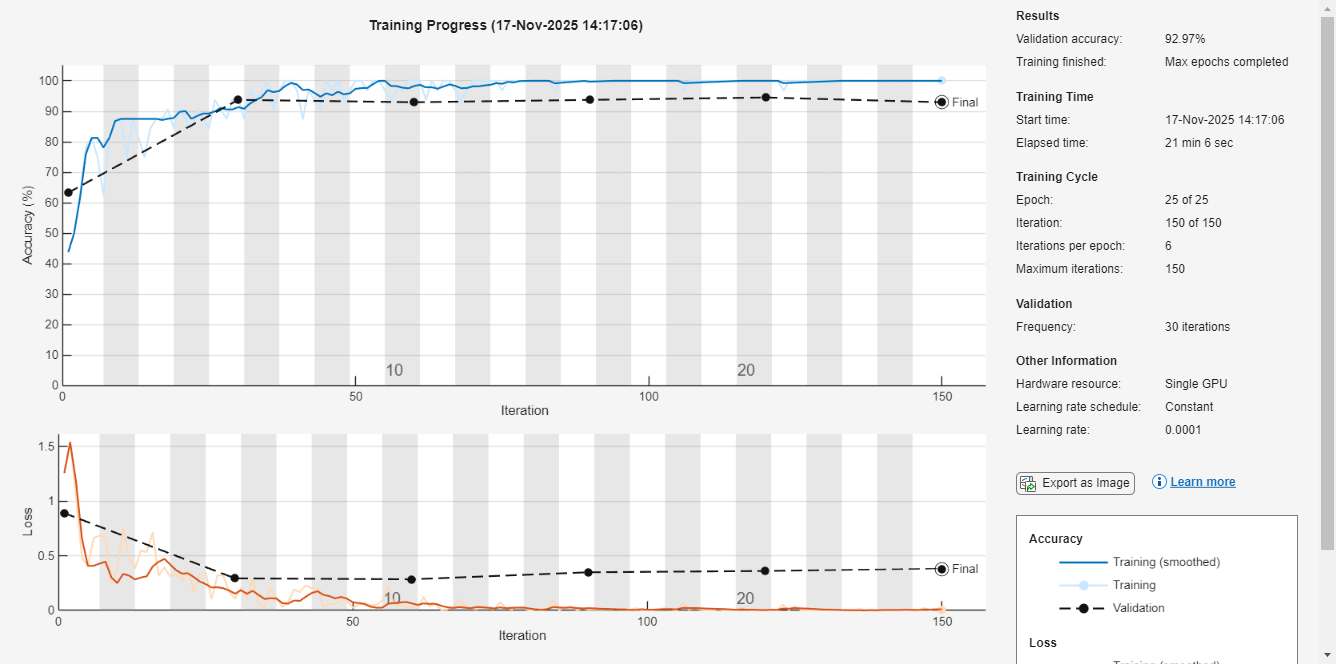

%% Training Options
options = trainingOptions("sgdm", ...
    "MiniBatchSize",32, ...
    "MaxEpochs",25, ...
    "InitialLearnRate",1e-4, ...
    "Shuffle","every-epoch", ...
    "ValidationData",augVal, ...
    "ValidationFrequency",30, ...
    "Verbose",false, ...
    "Plots","training-progress");

%% Train Network
trainedNet = trainNetwork(augTrain,layers,options);

%% Evaluate
[YPred, probs] = classify(trainedNet, augVal);
YTrue = imdsVal.Labels;

% Validation Accuracy
accuracy = mean(YPred == YTrue);
fprintf("Validation Accuracy: %.2f%%\n", accuracy*100);

Validation Accuracy: 92.97%


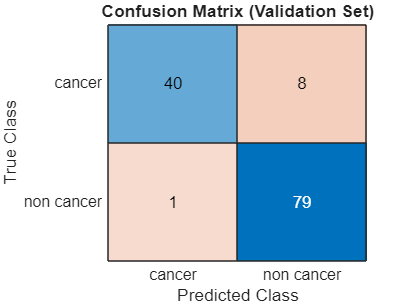


%% Confusion Matrix 
figure;
cmChart = confusionchart(YTrue, YPred, ...
    'Title','Confusion Matrix (Validation Set)', ...
    'RowSummary','off', ...
    'ColumnSummary','off');
cmChart.XLabel = 'Predicted Class';
cmChart.YLabel = 'True Class';


%% Metrics: Precision, Recall, F1-score
cm = confusionmat(YTrue, YPred);

precision = diag(cm) ./ sum(cm,2);
recall    = diag(cm) ./ sum(cm,1)';
f1score   = 2 * (precision .* recall) ./ (precision + recall);

order = categories(YTrue);
numClasses = numel(order);

for i = 1:numClasses
    fprintf("Class: %s | Precision: %.2f | Recall: %.2f | F1-Score: %.2f\n", ...
        string(order(i)), precision(i)*100, recall(i)*100, f1score(i)*100);
end

Class: cancer | Precision: 83.33 | Recall: 97.56 | F1-Score: 89.89
Class: non cancer | Precision: 98.75 | Recall: 90.80 | F1-Score: 94.61


Testing

%% -------- Test all images in a folder --------
testFolder = 'C:\Users\Loren Ruth\Downloads\datatest';
testFiles = dir(fullfile(testFolder, '*.jpg'));

YPred = [];
YTrue = [];  % only works if you have class subfolders

for k = 1:numel(testFiles)
    % Load image
    imgPath = fullfile(testFolder, testFiles(k).name);
    testImg = imread(imgPath);

    % Convert grayscale → RGB if needed
    if size(testImg,3) == 1
        testImg = repmat(testImg,[1 1 3]);
    end

    % Resize for VGG16
    testImgResized = imresize(testImg, [224 224]);

    % Predict
    predictedLabel = classify(trainedNet, testImgResized);

    % Store prediction
    YPred(k,1) = predictedLabel;

    % Show result
    figure;
    imshow(testImg);
    title({['File: ', testFiles(k).name], ...
           ['Predicted: ', char(predictedLabel)]});

    % Print in command window
    disp(['File: ', testFiles(k).name, ...
          ' | Predicted Class: ', char(predictedLabel)]);
end
